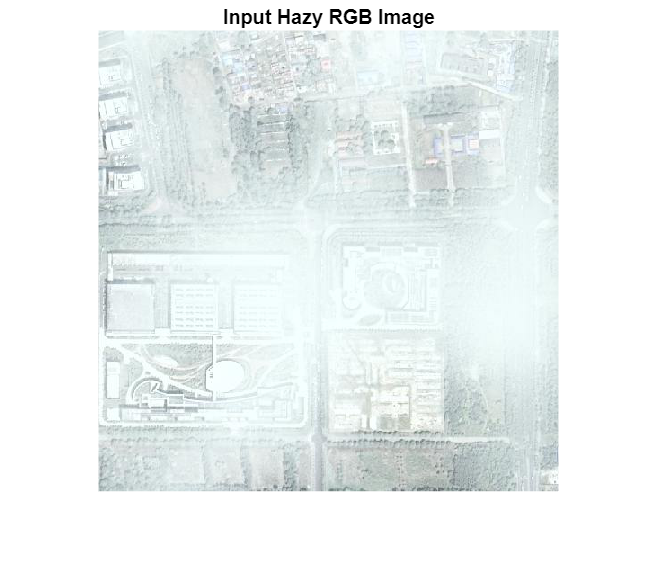

clc; clear; close all;
%read image
I = im2double(imread("D:\Downloads\Haze1k\Haze1k\Haze1k_thick\dataset\train\input\53-inputs.png"));
assert(size(I,3)==3,'Input must be RGB');
[h,w,~] = size(I);

figure; imshow(I); title('Input Hazy RGB Image');

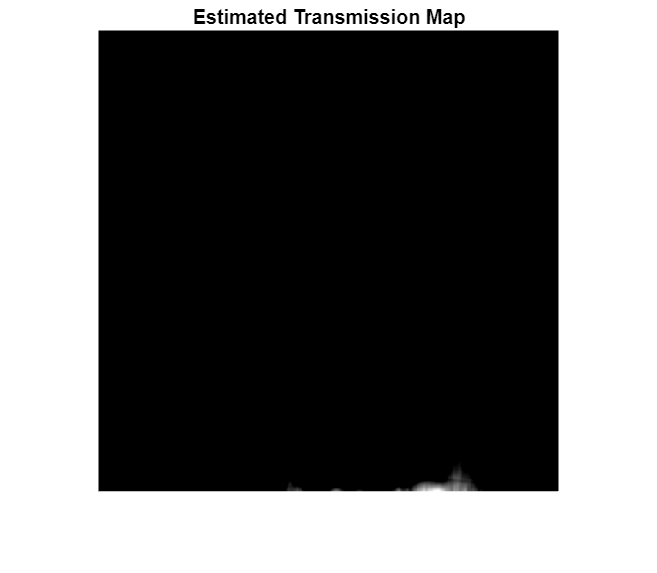


% ATMOSPHERIC LIGHT ESTIMATION
I_gray = rgb2gray(I);
sortedPixels = sort(I_gray(:),'descend');
topPixels = sortedPixels(1:round(0.001*numel(sortedPixels)));
A_gray = mean(topPixels);
A = [A_gray A_gray A_gray];

% TRANSMISSION ESTIMATION
W = fspecial('average',[15 15]);
t0 = 1 - imfilter(I_gray, W, 'replicate');
t0 = min(max(t0,0.3),0.9);

figure; imshow(t0,[]); title('Estimated Transmission Map');


% HAZE STRENGTH ESTIMATION
hazeStrength = mean(1 - t0(:));

disp(['Estimated Haze Strength: ', num2str(hazeStrength)]);

Estimated Haze Strength: 0.69982


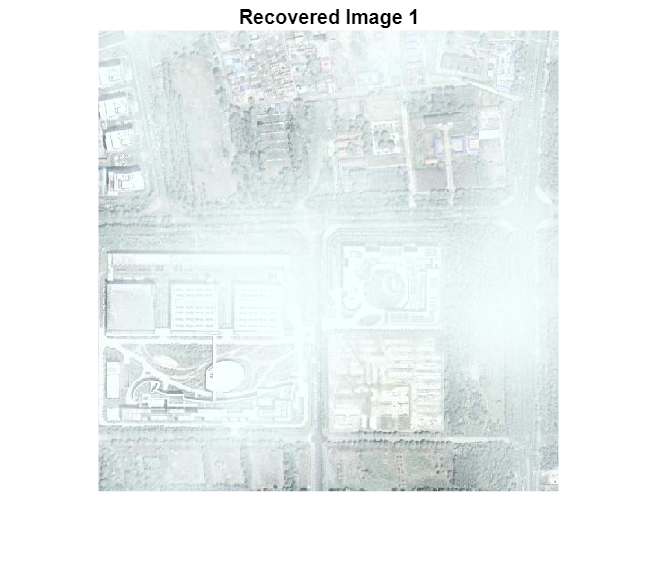

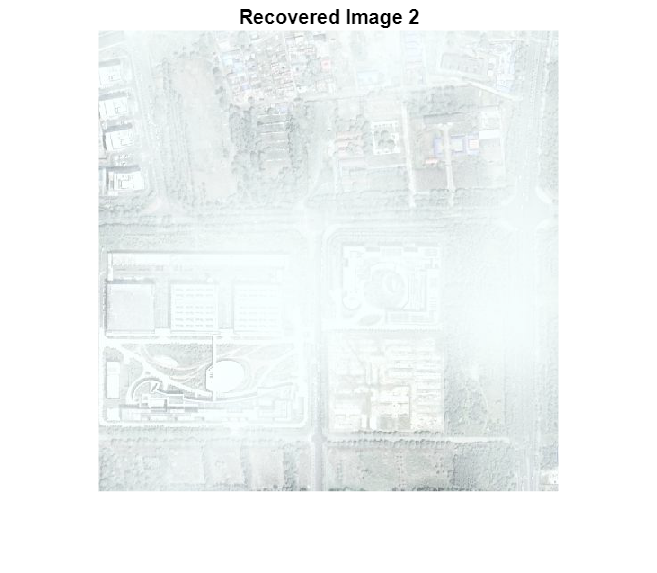

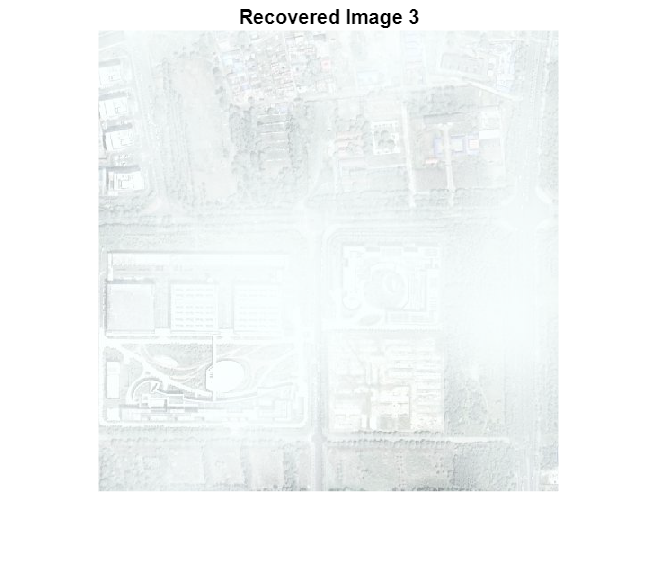

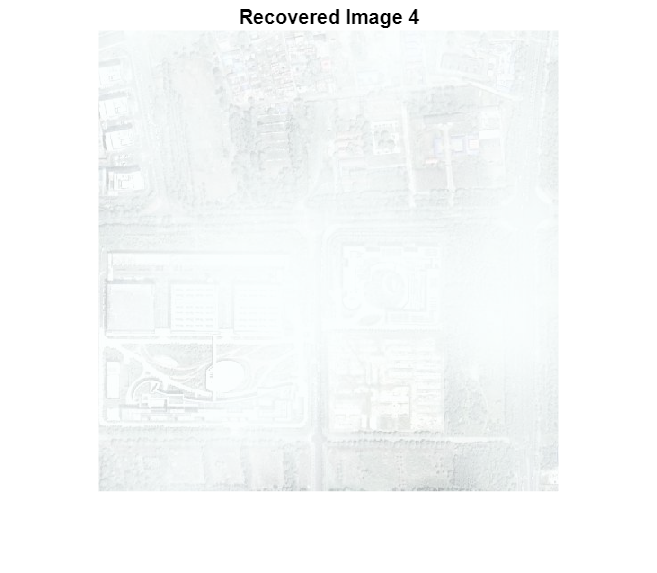


% ADAPTIVE PARAMETER SELECTION
numSamples = 4;
blurSet = [5 11 21 31];

if hazeStrength > 0.6
    % Thick haze
    lambdaSet = [0.2 0.3 0.4 0.6];
else
    % Thin / Moderate haze
    lambdaSet = [0.05 0.10 0.20 0.35];
end

% CVAE-STYLE UNCERTAINTY SAMPLING
Jset = zeros(h,w,3,numSamples);

for k = 1:numSamples

    % Transmission variation
    Wk = fspecial('average',[blurSet(k) blurSet(k)]);
    tk = 1 - imfilter(I_gray, Wk, 'replicate');
    tk = min(max(tk,0.25),0.95);

    lambda = lambdaSet(k);

    % ===== REGULARIZED PSEUDO-INVERSE =====
    H_pinv = tk ./ (tk.^2 + lambda);

    for c = 1:3
        Jset(:,:,c,k) = H_pinv .* (I(:,:,c) - A(c)) + A(c);
    end

    Jset(:,:,:,k) = min(max(Jset(:,:,:,k),0),1);

    figure;
    imshow(Jset(:,:,:,k));
    title(['Recovered Image ',num2str(k)]);
end

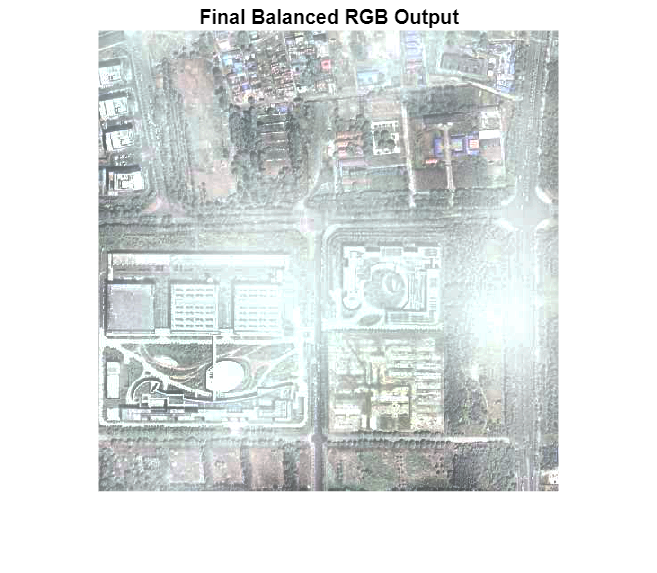


% FREQUENCY-DOMAIN FUSION
Ffused = zeros(h,w,3);

for c = 1:3
    Fsum = zeros(h,w);
    for k = 1:numSamples
        Fsum = Fsum + fft2(Jset(:,:,c,k));
    end
    Ffused(:,:,c) = real(ifft2(Fsum / numSamples));
end

Ffused = min(max(Ffused,0),1);

% THICK HAZE CONTRAST RECOVERY
if hazeStrength > 0.6
    for c = 1:3
        Ffused(:,:,c) = adapthisteq( ...
            Ffused(:,:,c), ...
            'ClipLimit',0.01, ...
            'Distribution','rayleigh');
    end
end

% RGB COLOR CORRECTION
meanRGB_I = squeeze(mean(mean(I,1),2));
meanRGB_J = squeeze(mean(mean(Ffused,1),2));

scale = meanRGB_I ./ meanRGB_J;
scale = min(max(scale,0.9),1.1);

for c = 1:3
    Ffused(:,:,c) = Ffused(:,:,c) * scale(c);
end

Ffused = min(max(Ffused,0),1);

% DISPLAY & SAVE RESULT
figure;
imshow(Ffused);
title('Final Balanced RGB Output');


imwrite(Ffused,'final_dehazed_image.png');
disp('Output saved as final_dehazed_image.png');

Output saved as final_dehazed_image.png



% Dehazed Image
hazeRemoved = I - Ffused;

% Frobenius Norm Computation
norm_input = sqrt(sum(I(:).^2));
norm_output = sqrt(sum(Ffused(:).^2));
norm_removed = sqrt(sum(hazeRemoved(:).^2));

% Percentage haze removed
hazeReductionPercent = (norm_removed / norm_input) * 100;

disp('FROBENIUS NORM ANALYSIS');

FROBENIUS NORM ANALYSIS


disp(['Input Energy        : ', num2str(norm_input)]);

Input Energy        : 799.4276


disp(['Output Energy       : ', num2str(norm_output)]);

Output Energy       : 717.0184


disp(['Haze Removed Energy : ', num2str(norm_removed)]);

Haze Removed Energy : 112.4214


disp(['Haze Reduction %  : ', num2str(hazeReductionPercent)]);

Haze Reduction %  : 14.0627
